**Sprawozdanie**

**Modelowanie 1/4 zawieszenie samochodu**

**Jakub Szczypek nr.405912**

**WEAIiIB air**

Wykonano model w Simulinku w oparciu o równanie z konspektu z wykorzystaniem bloczka ,,state space”. W tym celu zdefiniowano następujące dane i macierze:

m1 = 90

m1 = 90

m2 = 600

m2 = 600

k1 = 370000

k1 = 370000

k2 = 35000

k2 = 35000

c1 = 100

c1 = 100

c2 = 2000

c2 = 2000

A = [0 0 1 0 ; 0 0 0 1 ; -(k1+k2)/m1 k2/m1 -(c1+c2)/m1 c2/m1 ; k2/m2 -k2/m2 c2/m2 -c2/m2]

A = 	1.0e+03 *

         0         0    0.0010         0
         0         0         0    0.0010
   -4.5000    0.3889   -0.0233    0.0222
    0.0583   -0.0583    0.0033   -0.0033


B = [c1/m1 ;0; k1/m1 - (c1+c2)*c1/m1^2 ; c1*c2/(m1*m2)]

B = 	1.0e+03 *

    0.0011
         0
    4.0852
    0.0037


C = [0 1 0 0]

C =      0     1     0     0


D = [0]

D = 0

[licz, mian] = ss2tf(A,B,C,D);

G = tf(licz, mian)

G =
 
          3.704 s^2 + 1.377e04 s + 2.398e05
  --------------------------------------------------
  s^4 + 26.67 s^3 + 4562 s^2 + 1.377e04 s + 2.398e05
 
Continuous-time transfer function.



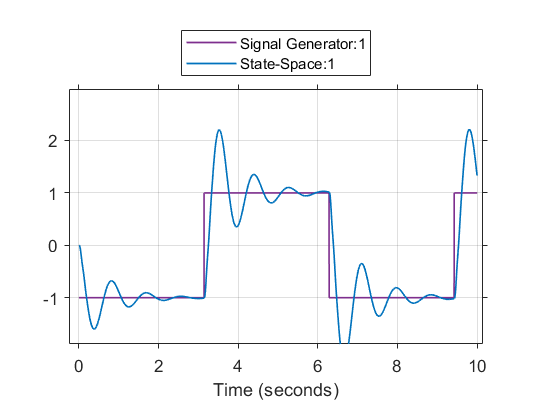

open("y_square.fig")

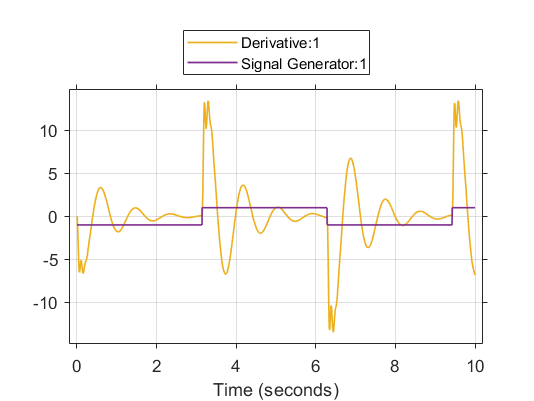

open("y'_square.fig")

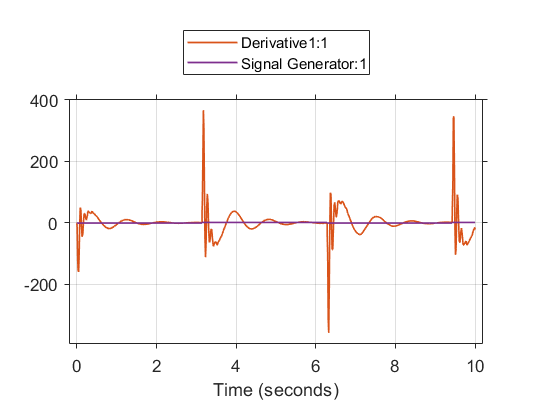

open("y''_square.fig")

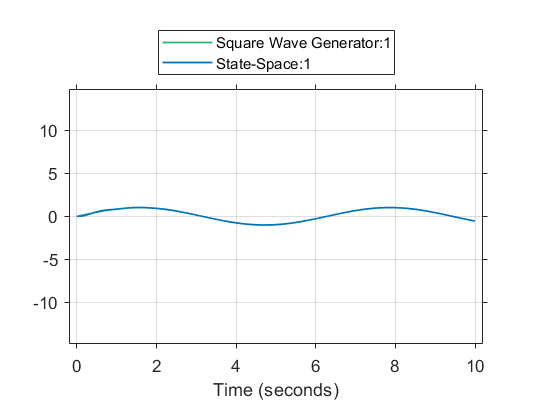

open("y_sin.fig")

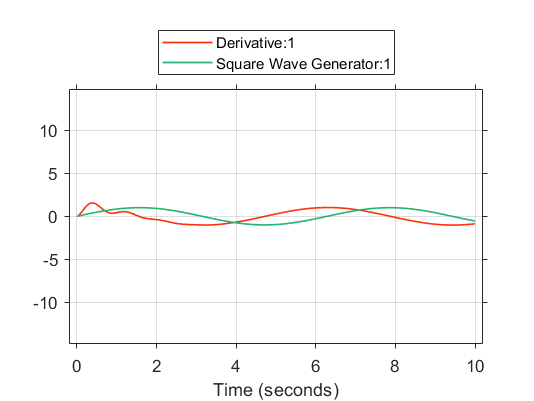

open("y'_sin.fig")

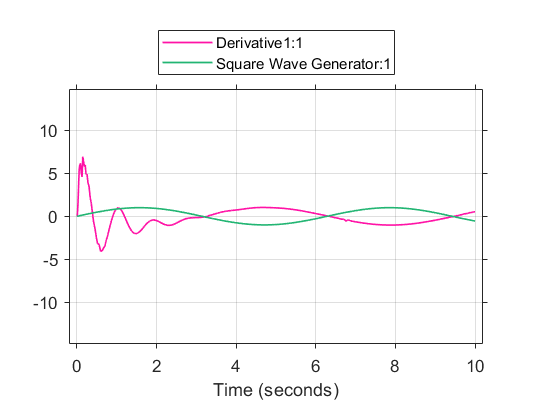

open("y''_sin.fig")

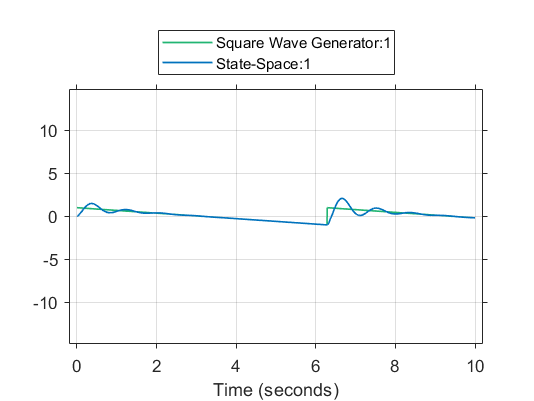

open("y_sawtooth.fig")

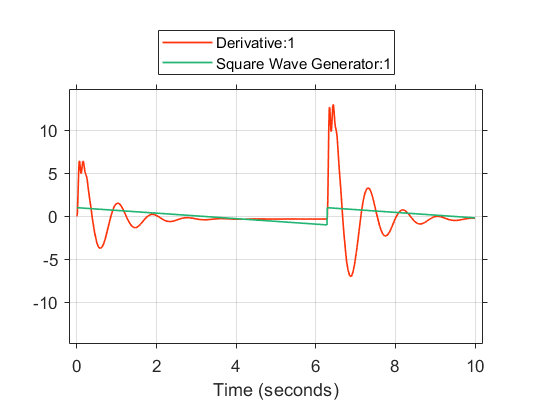

open("y'_sawtooth.fig")

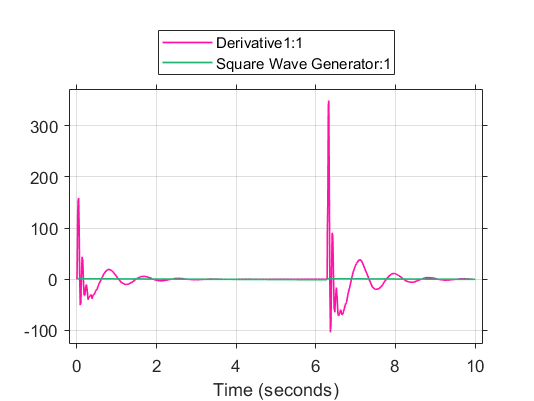

open("y''_sawtooth.fig")